# Eye pose parameters

The pose of the eye is described by the parameters:

`[azimuth, elevation, torsion, stopRadius]`

The three rotation variables are in units of degrees, and in the "Fick" (rotating) coordinate frame. The torsion value is the "true" torsion around the longitudinal axis of the model eye. There is an additional, "pseudo" torsion that is added by default to the pose of the eye to allow the model to comply with Listing's Law.

The stop radius is in units of millimeters, and provides the radius of the aperture in the iris. The size of the pupil, as seen by an observer looking at the eye, will be slightly different.

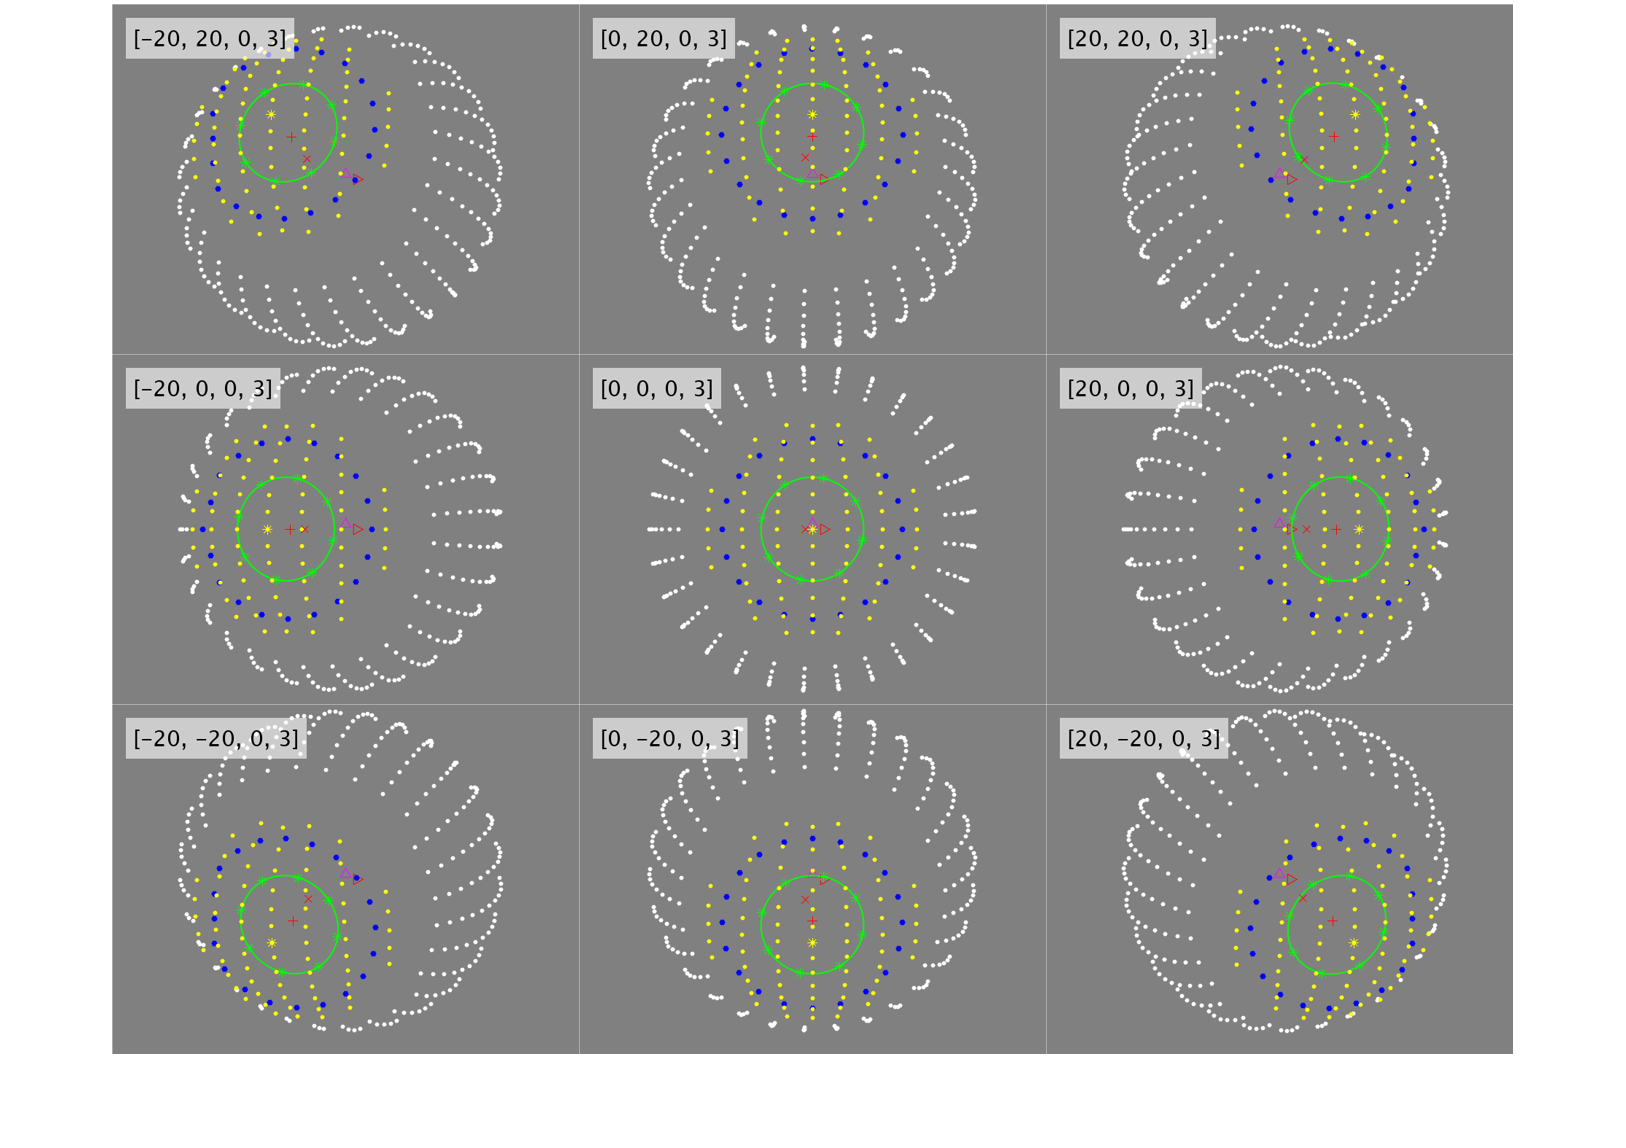

% Obtain the sceneGeometry
sceneGeometry = createSceneGeometry();

% Define some eye poses
eyePoses=[-20 20 0 3; 0 20 0 3; 20 20 0 3; -20 0 0 3; 0 0 0 3; 20 0 0 3; -20 -20 0 3; 0 -20 0 3; 20 -20 0 3 ];

% A variable to hold the rendered frames
I = cell(1,9);

% Loop over poses
for pp = 1:size(eyePoses,1)
    % Obtain the rendering of the model for this pose
    [figHandle, ~, renderedFrame] = renderEyePose(eyePoses(pp,:), sceneGeometry, 'visible', false);
    close(figHandle)
    I{pp}=insertText(renderedFrame.cdata,[20 20],sprintf('[%d, %d, %d, %d]',eyePoses(pp,:)),'FontSize',30,'BoxColor','white');
end

% Show the montage
figure
montage(I)